file='./ECMWF/2000_2019_monthly_pressure.nc'; %ncdisp(file);
windall.time = NaT(1,12*20);
for i = 1:20
    windall.time((i-1)*12+(1:12)) = datetime(1999+i,1:12,1);
end
windall.latitude=flip(double(ncread(file,'latitude')));
windall.longitude=double(ncread(file,'longitude'));
windall.pressure=double(ncread(file,'level'));
windall.alt = (1-(windall.pressure*100/101325).^(1/5.25588))/2.25577/10^(-5);
windall.u = permute(flip(ncread(file,'u'),2) , [2 1 4 3]); % m/s
windall.v = permute(flip(ncread(file,'v'),2) , [2 1 4 3]); % m/s
clear tmp_*

Fu = griddedInterpolant({windall.latitude,windall.longitude,datenum(windall.time),windall.alt},windall.u,'linear','linear');
Fv = griddedInterpolant({windall.latitude,windall.longitude,datenum(windall.time),windall.alt},windall.v,'linear','linear');

for i_d=1:numel(dc)
     dc(i_d).windallu = permute(Fu({dc(i_d).lat,dc(i_d).lon,datenum(windall.time),dc(i_d).alt}),[3,4,1,2]);
     dc(i_d).windallv = permute(Fv({dc(i_d).lat,dc(i_d).lon,datenum(windall.time),dc(i_d).alt}),[3,4,1,2]);
     dc(i_d).winddalltime = windall.time;
end

ida_esp = month(windall.time)==3;
ida_lsp = month(windall.time)==4;
ida_sp = ida_esp|ida_lsp;
ida_eau = month(windall.time)==8 | month(windall.time)==9;
ida_lau = month(windall.time)==10;
ida_au = ida_eau|ida_lau;
ida_s = [ida_esp; ida_lsp; ida_eau; ida_lau];
ida_s_name = {'March','April','Aug-sept.','October'};

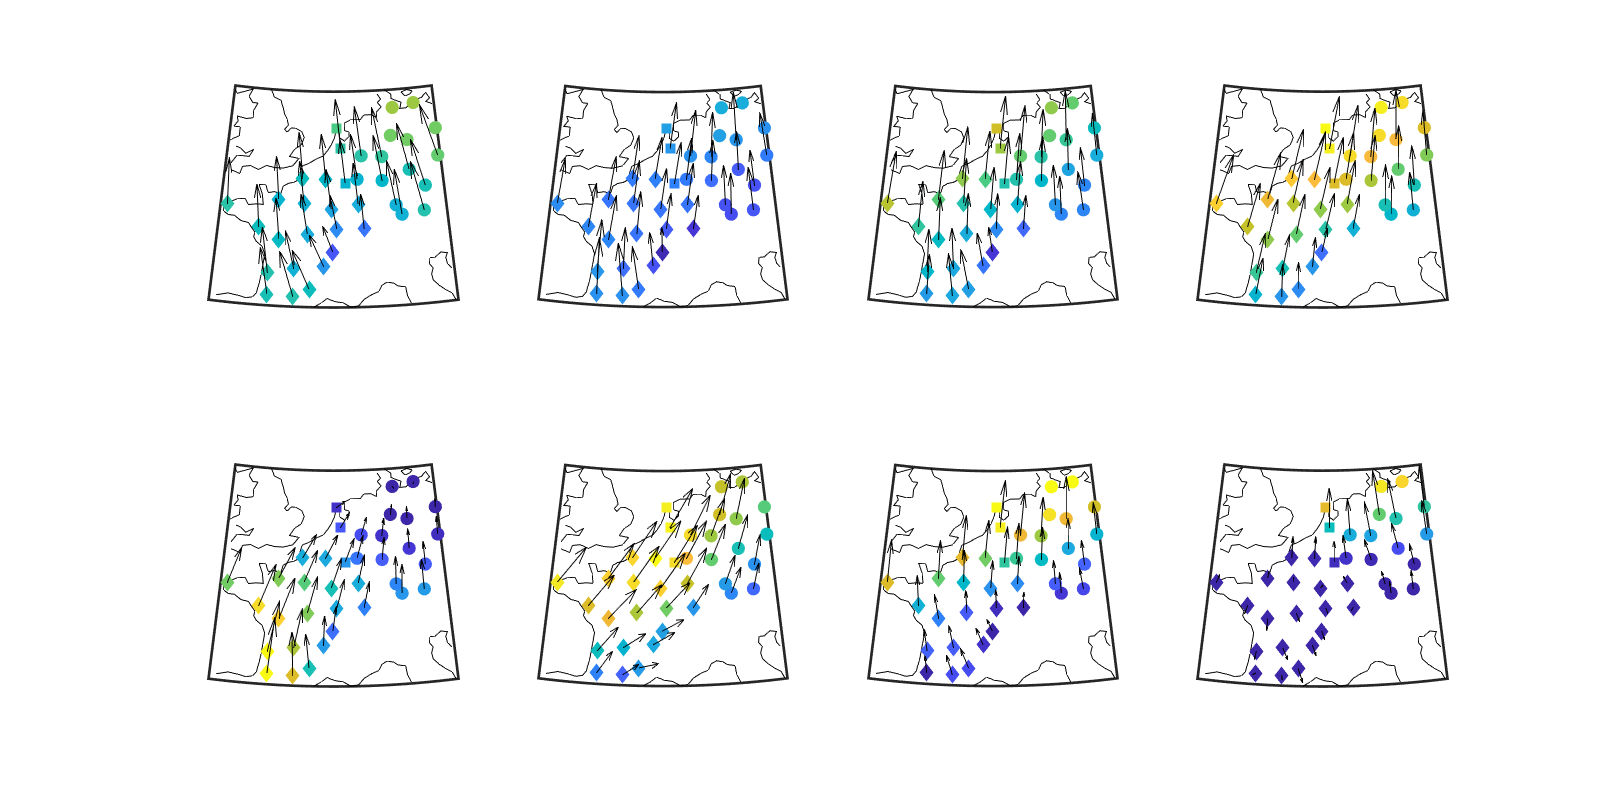

Mw=nan(numel(dc),size(id_s,1)); wu = Mw; wv=Mw;
for i_d = 1:numel(dc)
    for i_s = 1:size(ida_s,1)
        Mw(i_d,i_s) = nanmean(reshape(sqrt(dc(i_d).windallu(ida_s(i_s,:),:).^2 + dc(i_d).windallv(ida_s(i_s,:),:).^2),1,[]));
        wu(i_d,i_s) = nanmean(reshape(dc(i_d).windallu(ida_s(i_s,:),:),1,[]));
        wv(i_d,i_s) = nanmean(reshape(dc(i_d).windallv(ida_s(i_s,:),:),1,[]));
        
        Mw2018(i_d,i_s) = nanmean(reshape(sqrt(dc(i_d).windallu(ida_s(i_s,:) & year(windall.time)==2018,:).^2 + dc(i_d).windallv(ida_s(i_s,:) & year(windall.time)==2018,:).^2),1,[]));
        wu2018(i_d,i_s) = nanmean(reshape(dc(i_d).windallu(ida_s(i_s,:) & year(windall.time)==2018,:),1,[]));
        wv2018(i_d,i_s) = nanmean(reshape(dc(i_d).windallv(ida_s(i_s,:) & year(windall.time)==2018,:),1,[]));
    end
end

figure('position',[0 0 1600 800]);
for i_s = 1:size(ida_s,1)
    subplot(2,4,i_s); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mw(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mw(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mw(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',wu(:,i_s),wv(:,i_s),'k')
    caxis([3 8])
    
    subplot(2,4,4+i_s); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mw2018(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mw2018(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mw2018(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',wu2018(:,i_s),wv2018(:,i_s),'k')
    caxis([3 8])
end

First line: average 2000-2019, second line 2018. Column: Early, late spring and then autumn

Year 2018 corresponds to the data collected at the radar data level in pattern (GE less profitable wind than FR in Early spring) but the range of value is quite off (4-8 m/s instead of 6-16). not sure why. 

Average 2000-2019 does is more smooth than 2018 and doesn't have the same FR-GE pattern. 